Consider the confound of CAT image quality.

Mean: ratio of CAT parameter mean between sites

Variance: ratio of CAT parameter variance between sites

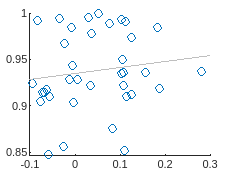

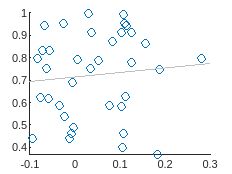

BD


                      Mean      Variance
                     _______    ________

    spearman corr    0.15367    0.10631 
    p                0.17092     0.2356 



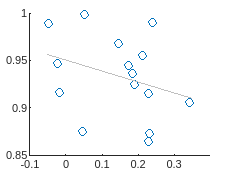

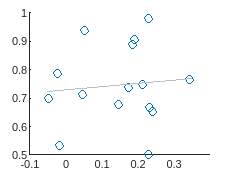

SCA


                       Mean      Variance 
                     ________    _________

    spearman corr    -0.36071    -0.014286
    p                0.048923       0.4627



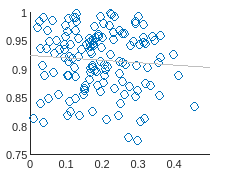

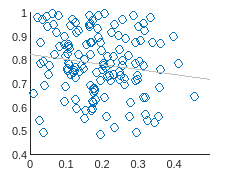

SCZ


                       Mean       Variance
                     _________    ________

    spearman corr    -0.050398     -0.1609
    p                  0.33614    0.079263



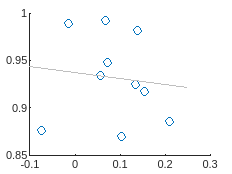

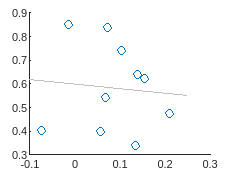

ASD


                       Mean      Variance 
                     ________    _________

    spearman corr    -0.22424    -0.042424
    p                  0.2699      0.48972



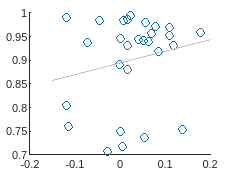

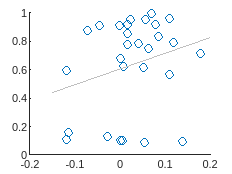

MDD


                      Mean      Variance
                     _______    ________

    spearman corr    0.12206    0.22551 
    p                0.32808       0.17 



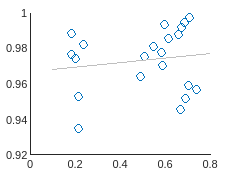

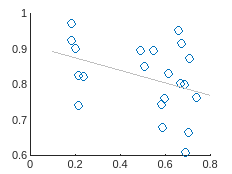

AD


                      Mean      Variance
                     _______    ________

    spearman corr    0.11039    -0.40519
    p                0.32493    0.042697



% Clear all variables and close all figures
clear all
close all

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is used
smoothKernel = 6; % Smoothing kernel size
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Correlation type (Spearman)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata about demographics and site information
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataVBM_extended.csv']);
% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat',num2str(iCOMBAT),'_smooth',num2str(smoothKernel),'.mat'], 'cor1', 'cor2',"siteList")

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to image quality and site correlation
    [varTable{iDiag} nSite{iDiag}]= cor_var_CAT(metadata, diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag},siteList{iDiag}, iter, type);
    % Display results if the variance table is not empty
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ')
    end
end


% Suppress specific warnings and save the results
warning('off','last')

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_CAT.mat','varTable','nSite')